# 第七次作业

## 心形线（选做）

用polarplot函数作图。面积为


$$A=\int_{0}^{2\pi}\frac{1}{2}r\cdot r{\rm d}r.$$


注意面积微元是一个腰为$r$，底为$r{\rm d}r$的三角形。

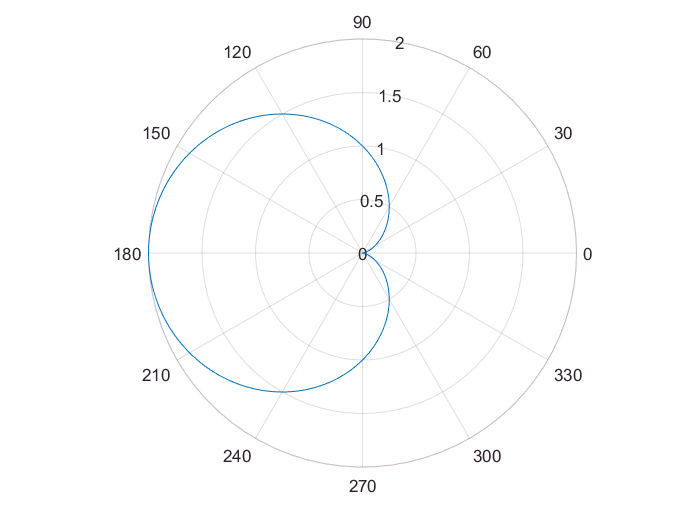

dlm = 0.01*pi;
t = 0:dlm:2*pi;
r = 1 - cos(t);
figure; polarplot(t, r);

area = trapz(r.^2/2)*dlm

area =    4.712388980384692

## 三个积分

第1个积分

integral3(@(x,y,z)x.*y.*z,1,2,@(x)x,@(x)2*x,@(x,y)x.*y,@(x,y)2*x.*y)

ans = 179.2969

integral(@(x)arrayfun(@(x)integral2(@(y,z)x.*y.*z,x,2*x,@(y)x.*y,@(y)2.*x.*y),x),1,2)

ans = 179.2969

integral(@(x)arrayfun(@(x)integral(@(y)arrayfun(@(y)integral(@(z)x.*y.*z,x.*y,2*x.*y),y),x,2*x),x),1,2)

ans = 179.2969

第2个积分


integral(@(x)1./arrayfun(@(x)integral(@(y)y,x,x.^2),x),10,100)

ans = 6.7003e-04

第3个积分

integral(@(y)2*y.*exp(-y.^2).*arrayfun(@(y)integral(@(x)exp(-x.^2)./(x.^2+y.^2),-1,1),y).^2,0.2,1)

ans = 10.2135

## 1 符号和数值积分

符号法

syms x; int(x^4*(1-x)^4/(1+x^2), x, 0, 1)

$$ans = \frac{22}{7}-\pi$$

数值法

X=0:0.1:1; trapz(X,X.^4.*(1-X).^4./(1+X.^2))

ans = 0.0013

integral(@(x)x.^4.*(1-x).^4./(1+x.^2), 0, 1)

ans = 0.0013

## 2 误差函数

format long; myerf = @(x)2/sqrt(pi)*integral(@(xi)exp(-xi.^2), 0, x); X=0.1:0.1:1.0; arrayfun(myerf,X), erf(X)

ans =    0.112462916018285   0.222702589210478   0.328626759459127   0.428392355046668   0.520499877813047   0.603856090847926   0.677801193837418   0.742100964707661   0.796908212422832   0.842700792949715

ans =    0.112462916018285   0.222702589210478   0.328626759459127   0.428392355046668   0.520499877813047   0.603856090847926   0.677801193837418   0.742100964707661   0.796908212422832   0.842700792949715

## 3 室温下氢分子运动速率的 Maxwell 分布

以$v_p$为速度量纲做无量纲化运算。以$x$代表$\frac{v}{v_p}$

f=@(x)4/sqrt(pi)*x.^2.*exp(-x.^2); integral(f,0,1),  integral(f,0,3.3),  integral(f,3e4/1578,3e8/1578)

ans =    0.427593295529120

ans =    0.999927519495740

ans =     9.367342245784810e-157

## 4 均匀带电圆环的电场

如果绘制二维图, 先计算电势，有：


$$V(\vec{r})=\oint_{C_a}\frac{\text{d}q}{4\pi\varepsilon_0|\vec{r}-\vec{r}_{\text{d}q}|}$$


令 $a = 1,q = 2π,y = 0$，则为


$$\int_0^{2\pi}\frac{\text{d}\phi}{(x-\cos{\phi})^2+\sin^2{\phi}+z^2};$$


再用 gradient 即可计算出电场强度。

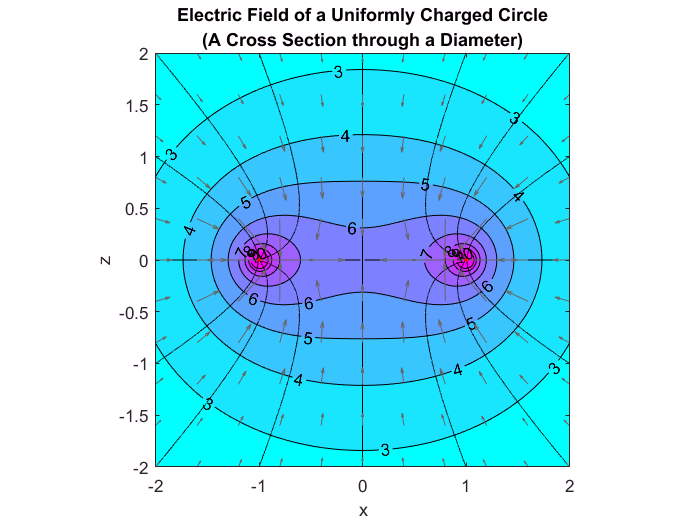

[x,z] = meshgrid(-2:.02:2);
phi = 0:0.1*pi:2*pi;
V = @(x,z)trapz(phi,1./sqrt((x-cos(phi)).^2+(sin(phi)).^2+z.^2));
Vdata = reshape(arrayfun(V, x, z), size(x));
[Ex, Ez] = gradient(Vdata);
figure; c = contourf(x, z, Vdata, 2:1:10, 'showtext', 'on'); colormap('cool');
hold on;
sl_left_bottom = streamline(x,z,Ex,Ez,[-2:1:2, -2*ones([1,5]), -.02], [-2*ones([1,5]), -2:1:2, 0], [.01,15000]);
set(sl_left_bottom, 'Color', 'k');
sl_right_top = copyobj(sl_left_bottom, gca);
rotate(sl_left_bottom, [0,0,1], 180);
quiver(x(1:20:end,1:20:end), z(1:20:end,1:20:end), Ex(1:20:end,1:20:end), Ez(1:20:end,1:20:end), 'Color', [.4,.4,.4], 'AutoScaleFactor', 2., 'MaxHeadSize', .05)
plot([-1, 1], [0, 0], 'r.');
axis equal; xlabel('x'); ylabel('z');
title({'Electric Field of a Uniformly Charged Circle', '(A Cross Section through a Diameter)'});

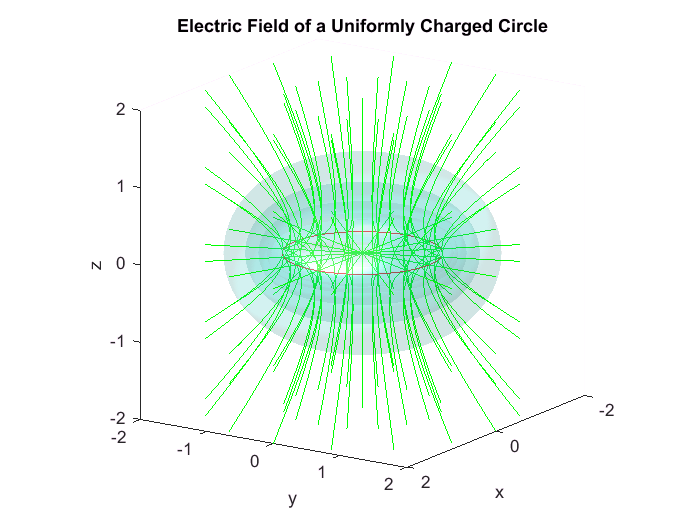

figure; hold on;
s1 = copyobj(sl_left_bottom, gca); s2 = copyobj(sl_right_top, gca);
s0 = allchild(gca); s = copyobj(s0, gca); delete(s0);
rotate(s, [1,0,0], 90, [0,0,0]); set(s, 'Color', 'g');
for k = 1:4
    ax = copyobj(allchild(gca),gca);
    rotate(ax, [0,0,1], 11.25*2^k, [0,0,0]);
end
c = contourdata(c);
phi = linspace(0, pi);
for k = 3:length(c)
    rho = c(k).xdata; z = c(k).ydata;
    [~,Z] = meshgrid(phi,z); [Phi,R] = meshgrid(phi,rho);
    [x,y,z] = pol2cart(Phi,R,Z);
    patch(surf2patch(x,y,z,ones(size(x))), 'FaceAlpha', .1); shading interp; light;
end
plot(exp(1i*[phi, pi + phi]),'r-','LineWidth',.1);
view([3,2,1]); axis equal;
axis equal; xlabel('x'); ylabel('y'); zlabel('z');
title('Electric Field of a Uniformly Charged Circle');

以圆环所在平面为 $xOy$ 坐标面，以环心为原点，则空间任意一点 ${\rm d}q$ 的电场强度为：


$$
	\vec{E}_p=\oint_{C_a}\frac{(\vec{r_P}-\vec{r_{\text{d}Q}})\text{d}(4\pi\varepsilon_{0}q)}{4\pi\varepsilon_{0}|\vec{r_P}-\vec{r_{\text{d}Q}}|^3}\\
	=\frac{q}{2\pi}\oint_{C_a}\frac{(\vec{r_P}-\vec{r_{\text{d}Q}})}{|\vec{r_P}-\vec{r_{\text{d}Q}}|^3}\text{d}\phi\\
	=\frac{q}{2\pi}\int_0^{2\pi}\frac{(x-a\cos{\phi},y-a\sin{\phi},z)}{\left[(x-a\cos{\phi})^2+(y-a\sin{\phi})^2+z^2\right]^{\frac{3}{2}}}\text{d}\phi$$


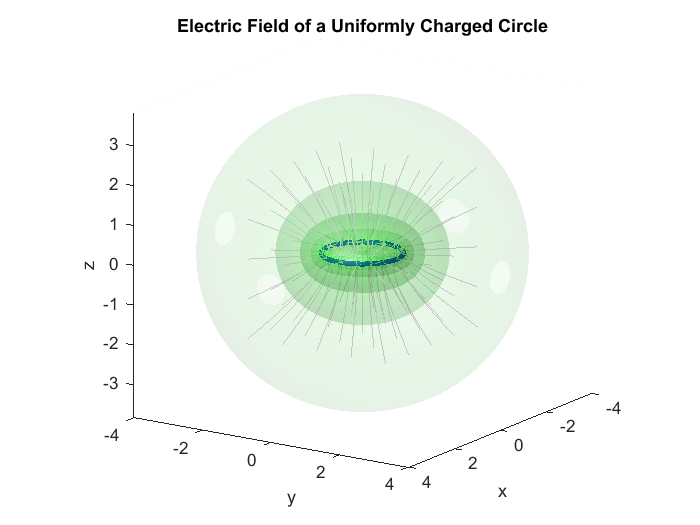

[x,y,z]=meshgrid(-4:.1:4);
V = zeros(81, 81, 81, 100);
for k = 1:100
    V(:,:,:,k) = 1./sqrt((x-cos((2*pi+.05)/100*k)).^2+(y-sin((2*pi+.05)/100*k)).^2+z.^2);
end
V = trapz(V, 4);
[Ex,Ey,Ez] = gradient(V, x(1,2,1)-x(1,1,1));
figure; hold on;
    [startx,starty] = meshgrid(-2:1:2); startz = -2*ones(size(startx));
    sSide = streamline(x,y,z,Ex,Ey,Ez,startx,startz,starty);
    rotate(copyobj(allchild(gca), gca), [0,0,1], 180, [0,0,0]);
    rotate(copyobj(allchild(gca), gca), [0,0,1], 90, [0,0,0]);
    sBottom = streamline(x,y,z,Ex,Ey,Ez,startx,starty,startz);
    sTop = copyobj(sBottom, gca);  rotate(sTop, [0,1,0], 180, [0,0,0]);
    [startx, starty] = deal(.1*cos(linspace(0, 2*pi, 16)), .1*sin(linspace(0, 2*pi, 16))); startz = zeros(size(startx));
    streamline(x,y,z,Ex,Ey,Ez,startx,starty,startz);
    set(allchild(gca), 'color', [.8,.8,.8]);
    t = 0:pi/20:2*pi; plot(exp(1i*t),'b-','LineWidth',3);
    for k = 1:5
        patch(isosurface(x,y,z,V,25*k),'FaceAlpha',0.05*k,'LineStyle','none','FaceColor','green');
    end
    light;
    view([3,2,1]); axis equal;
axis equal; xlabel('x'); ylabel('y'); zlabel('z');
title('Electric Field of a Uniformly Charged Circle');

## 5 Helmholtz

绘图

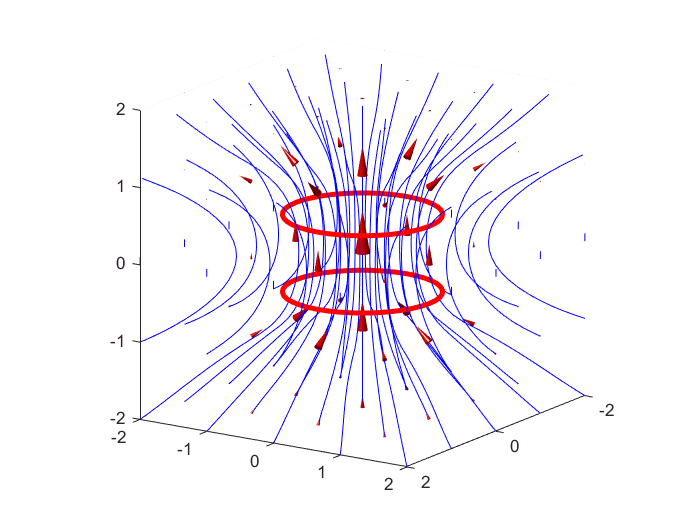

figure; helmholtzfun(1,1,1);
axis equal; axis([-2,2,-2,2,-2,2]); view([3,2,1]);

变化距离

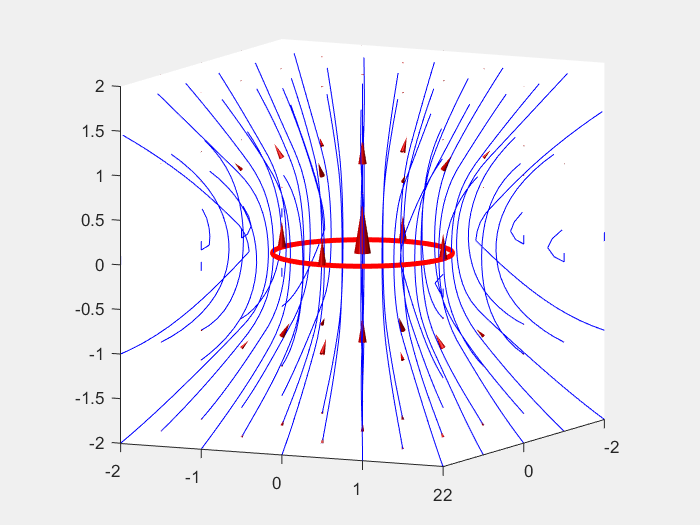

hscale = 0:0.1:1.2;
figure('visible', 'on');

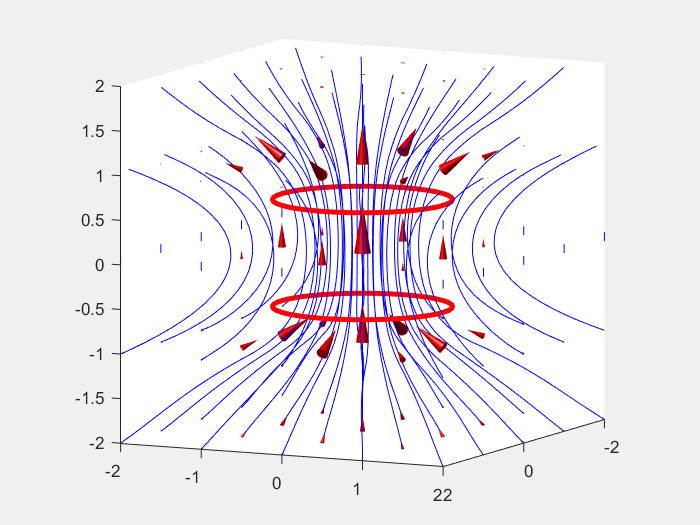

for k = 1:length(hscale)
    helmholtzfun(1,1,hscale(k));
    axis equal; axis([-2,2,-2,2,-2,2]);
    view([6,3,1]); getframe;
end

变化下环半径

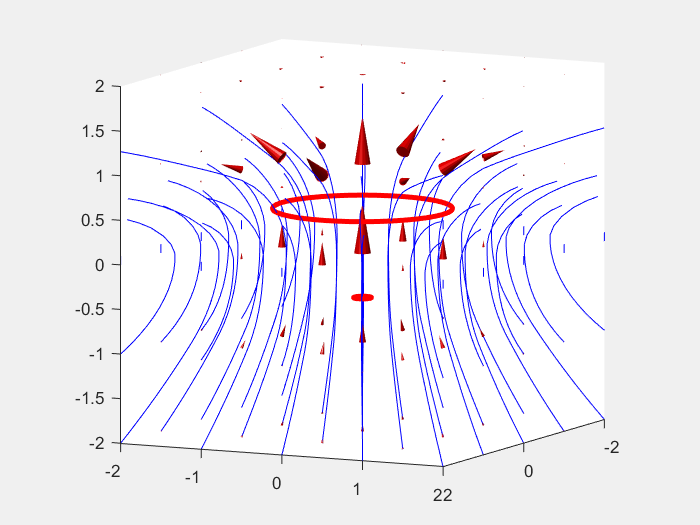

Rdscale = .1:.1:2;
figure('visible', 'on');

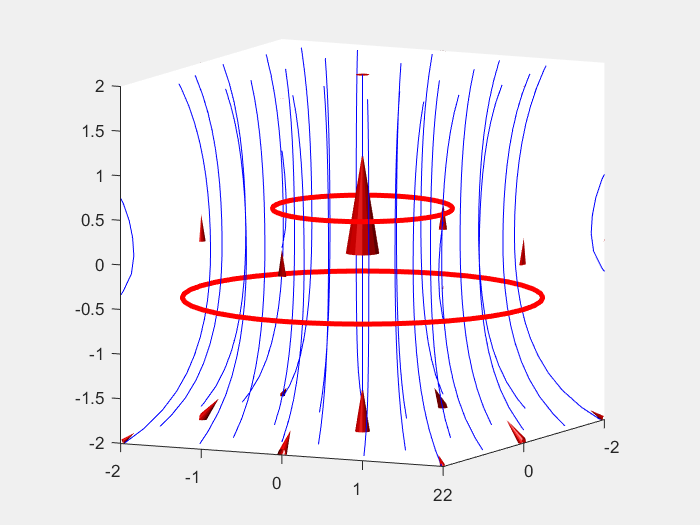

for k = 1:length(Rdscale)
    helmholtzfun(1,Rdscale(k),1);
    axis equal; axis([-2,2,-2,2,-2,2]);
    view([6,3,1]); getframe;
end

# 链接

- [下载此页对应的实时脚本](https://wang-guosheng.github.io/CompPhyExs/ex7.mlx)

- [下载此页对应的PDF](https://wang-guosheng.github.io/CompPhyExs/ex7.pdf)

- [主页](https://wang-guosheng.github.io/CompPhyExs/main.html)

- [下一页](https://wang-guosheng.github.io/CompPhyExs/ex8.html)

- [contourdata 函数下载](https://ww2.mathworks.cn/matlabcentral/fileexchange/38863-extract-contour-data-from-contour-matrix-c)

- [helmholtzfun 函数](https://wang-guosheng.github.io/CompPhyExs/helmholtzfun.html)